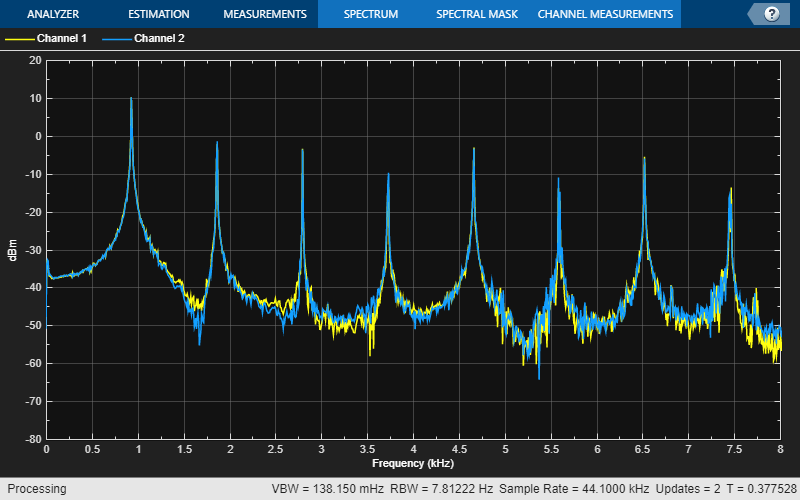

ans =    -0.0001   -0.0158
   -0.0211   -0.0243
   -0.0391   -0.0447
   -0.0235   -0.0399
   -0.0391   -0.0439
   -0.0724   -0.0676
   -0.0634   -0.0720
   -0.0654   -0.0835
   -0.0887   -0.1045
   -0.0981   -0.1033


clc
clear all
close all
warning off
syms x
% AV_Info %Shows inputs/outputs of audio on device
% Microphone ID: 1
% Speakers ID: 3

SampleRate = 44100; %Sample Rate of Audio Recording in Hertz

NumberBits = 16; %Number of bits per sample

RecordingLength = 5; %Length of recording in seconds

FileName = 'ECE 2312 C24\TQBF jumps over lazy dog.wav'; %Name of file to be written/loaded

Channels = 1; %Channels to be recorded, 1: mono, 2: stereo

DeviceID = 1; %ID of Device to be used

DelaySide = 2; %Determines which ear will have the stereo delay, 1 for left, 2 for right

DelayLength = 1000; %Length of Stereo Delay in ms

%initializes figures to be used for plotting
%without this, calling PlotAudioTime or PlotAudioSpectrum after the other
%would overwrite the previous plot
f1=figure;
f2=figure;


t = linspace(0, 5, SampleRate*5)'; % SampleRate*RecordingLenth elements linearly spaced going from 0-5
F = 5000; % Sine wave frequency in Hertz
sin5000Hz = sinpi(2*F*t); %generates sine wave. sinpi includes pi in the function...
% ...automatically and is more accurate than adding a rounded pi within the function
% plot(t, sin5000Hz);
% axis([0 1/5000 -1 1]);
% grid on;
%sound(sin5000Hz, SampleRate);

% Generate the chirp signal using the sin function
t = linspace(0, 8000, SampleRate*5)'; %Frequency linearly goes from 0-8000Hz
sin8000HzChirp = sinpi(2*cumsum(t)/SampleRate);







% sound(sin8000HzChirp, SampleRate);
%F = linspace(0, 8000, SampleRate*5);
%sine8000HzChirp = sinpi(2*t*cumsum(F)/SampleRate);
% sound(sine8000HzChirp, SampleRate);





[AudioData, SampleRate] = audioread("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\CETK 5 Tones.wav");
%PlotAudioTime(AudioData, SampleRate, f1)
%PlotAudioSpectrogram(AudioData, SampleRate, f2, 8000)
scope = spectrumAnalyzer(SampleRate = SampleRate,...
     AveragingMethod = "exponential", PlotAsTwoSidedSpectrum = false,...
     FrequencySpan = "start-and-stop-frequencies", StartFrequency = 0,...
     StopFrequency = 8000);
t = linspace(1,16650,16650);
scope(AudioData(t,:));


scope.PeakFinder 

%Attenuation was found using signal normalized to 0dB in Audacity.

%1st note length: 0-16,650 Samples (~0.378 Seconds Long)
%2nd note length: 16,650-38,700 Samples (22,050 Samples Long, ~0.5 Seconds Long)
%3rd note length: 38,700 - 71,800 Samples (33,100 Samples Long, ~0.751
%Seconds Long) (Attenuation from 60,750 Samples to end), ends on -20.1dB
%4th note length: 71,800 - 93,800 Samples (22,000 Samples Long, ~0.499
%Seconds Long)
%5th note length: 93,800 - 178,000 Samples (84,200 Samples Long), ~1.909
%Seconds Long. Attenuation 1
%(freq. is from audacity)
%1st note pitch: A#5 (930Hz, -8.9dB), A#6 (1867Hz, -21.2dB), F7 (2803Hz, -24dB)
%2nd note pitch: 
%3rd note pitch:
%4th note pitch:
%5th note pitch:



function AV_Info
av = audiodevinfo;
av.input
av.output
end

%add a slight attack to the signal?

function Wave = SineGen (Freq1, Freq2, Freq3, Freq1dB, Freq2dB, Freq3dB, Fs, Length)
t = linspace(0, Length, Fs*Length)';
Wave = (10^(Freq1dB/20))*sinpi(Freq1*2*t) + (10^(Freq2dB/20))*sinpi(Freq2*2*t) + (10^(Freq3dB/20))*sinpi(Freq3*2*t);
end


% function WaveAttenuated (Wave, Fs, attenLength, minVoldB)
% t = linspace()
% t = paddata()
% WaveAttenuated = 
% end





function PlotAudioTime (Audio, Fs, fig)
N=length(Audio);
t = linspace(0, N/Fs, N);
figure(fig);
    if size(Audio, 2) == 1
        plot(t, Audio)
        xlabel('Time, (s)')
        ylabel('Amplitude')
        title('Mono Audio Signal')
        grid on
    elseif size(Audio, 2) == 2
        tiledlayout(2, 1);
        ax1=nexttile;
        plot(t, Audio(:, 1))
        title(ax1, 'Audio Signal Left')
        ylabel(ax1, 'Amplitude')
        xlabel(ax1, 'Time (s)')
        grid on
        ax2=nexttile;
        plot(t, Audio(:, 2))
        title(ax2, 'Audio Signal Right')
        ylabel(ax2, 'Amplitude')
        xlabel(ax2, 'Time (s)')
        grid on
    end
end

function PlotAudioSpectrogram(Audio, Fs, fig, FMax)
figure(fig);
F=linspace(0, FMax, 200);
    if size(Audio, 2) == 1
        spectrogram(Audio, hamming(512), 128, F, Fs,'yaxis','power')
        title('Mono Audio Spectrogram')
    elseif size(Audio, 2) == 2
        tiledlayout(2, 1);
        nexttile
        spectrogram(Audio(:, 1), hamming(512), 128, F, Fs, 'yaxis', 'power')
        title('Audio Left Spectrogram')
        nexttile
        spectrogram(Audio(:, 2), hamming(512), 128, F, Fs, 'yaxis', 'power')
        title('Audio Right Spectrogram')
    end
end

function Audio = RecordAudio(Fs, NBits, Ch, ID, Len)
recorder=audiorecorder(Fs, NBits, Ch, ID);
disp('Start speaking..')
%Record audio to audiorecorder object,...
...hold control until recording completes
recordblocking(recorder, Len);
disp('End of Recording.');
%Store recorded audio signal in numeric array
Audio = getaudiodata(recorder);
end

function Audio = StereoDelay(Audio, Fs, Delay, Side)
FsPerms = Fs/1000;
NumZeros = round(FsPerms*Delay);
if size(Audio, 2) == 1
    if Side == 1
        Audio = [paddata(Audio, NumZeros+length(Audio), Side='leading'),... 
            paddata(Audio, NumZeros+length(Audio), Side='trailing')];
    elseif Side == 2
        Audio = [paddata(Audio, NumZeros+length(Audio), Side='trailing'),... 
            paddata(Audio, NumZeros+length(Audio), Side='leading')]; 
    end
elseif size(Audio, 2) == 2
    if Side == 1
        Audio = [paddata(Audio(:, 1), NumZeros+length(Audio),Side='leading'),... 
            paddata(Audio(:, 2), NumZeros+length(Audio), Side='trailing')];
    elseif Side == 2
        Audio = [paddata(Audio(:, 1), NumZeros+length(Audio),Side='trailing'),... 
            paddata(Audio(:, 2), NumZeros+length(Audio), Side='leading')];
    end
end
end
